# Optimization and Data Analytics HW8

## An Introduction to Optimization sec. 8

## Exercise 8.8

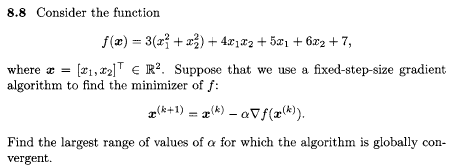

The function $f(x)$

f = @(x1,x2) 3*(x1^2+x2^2)+4*x1*x2+5*x1+6*x2+7;

may be expressed by the matrix expression:


$$f(x)=\mathbf{x}^TA\mathbf{x}+\mathbf{b}\mathbf{x}+c=\mathbf{x}^T\left\lbrack \begin{array}{c}
3 & 2\\
2 & 3
\end{array}\right\rbrack\mathbf{x}+\left\lbrack \begin{array}{c}
5\\
6
\end{array}\right\rbrack\mathbf{x}+7$$


A = [3 2; 
    2 3]

A =      3     2
     2     3



A'

ans =      3     2
     2     3


The quadratic function is rewritten to the form:


$$f(x)=\frac{1}{2}*\mathbf{x}^TQ\mathbf{x}-\mathbf{b}^T\mathbf{x}$$


Where $Q$ is a symmetric matrix, which is given by:


$$Q=A+A^T$$


Q = A+A'

Q =      6     4
     4     6


Then for a fixed-step-size gradient algorithm, the algorithm is globally convergent when $\alpha$is within the range:


$$0<\alpha<\frac{2}{\lambda_{max}(\mathbf{Q})}$$


The eigenvalues of $Q$ are given by:

eig_max = eigs(Q,1) % returns eigenvector with largest magnitude

eig_max = 10

The range of $\alpha$is then:

syms a
range = 0 < a < (2/eig_max)

$$range = \left(0<a\right)<\frac{1}{5}$$

## Exercise 8.16

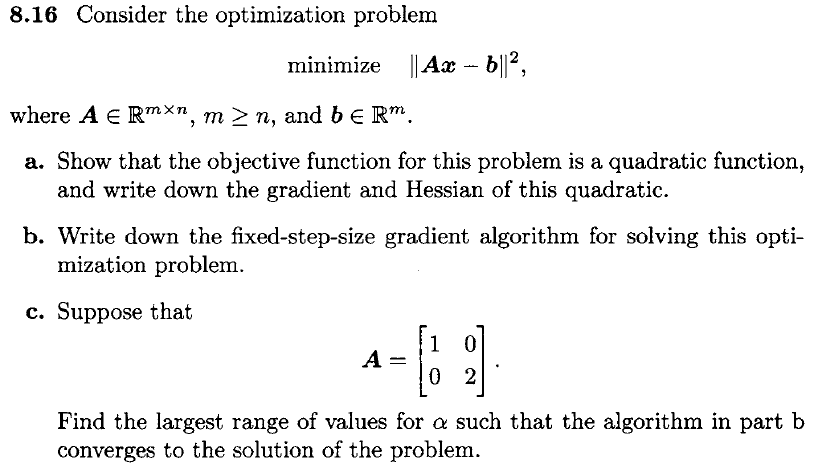

## a)

The quadratic form of the objective function is given by:


$$||Ax-b||^2=(Ax-b)^T(Ax-b)=(x^TA^T-b^T)(Ax-b)=x^T(A^TA)x-2*(A^Tb)x+b^Tb$$


syms A b x
f = @(x) x'*(A'*A)*x-2*(A'*b)*x+b'*b;
gradient = diff(f,x)

$$gradient = A\,\bar{A}\,\bar{x}-2\,b\,\bar{A}+A\,x\,\bar{A}$$

hessian = diff(f,x,x)

$$hessian = 2\,A\,\bar{A}$$

## b)

The fixed-step-size gradient algorithm is given by:


$$x^{(k+1)}=x^{(k)}-\alpha\nabla f(x^{(k)})$$


Which for this function is:


$$x^{(k+1)}=x^{(k)}-\alpha(2(A^TA)x^{(k)}-2bA^T)=-2\alpha A^T(Ax^{(k)}-b)$$


## c)

A = [1 0; 
    0 2]

A =      1     0
     0     2


A'

ans =      1     0
     0     2


The quadratic function is rewritten to the form:


$$f(x)=\frac{1}{2}*\mathbf{x}^TQ\mathbf{x}-\mathbf{b}^T\mathbf{x}$$


Where $Q$ is a symmetric matrix, which is given by:


$$Q=A+A^T$$


Q = A+A'

Q =      2     0
     0     4


Then for a fixed-step-size gradient algorithm, the algorithm is globally convergent when $\alpha$is within the range:


$$0<\alpha<\frac{2}{\lambda_{max}(\mathbf{Q})}$$


The eigenvalues of $Q$ are given by:

eig_max = eigs(Q,1) % returns eigenvector with largest magnitude

eig_max = 4

The range of $\alpha$is then:

syms a
range = 0 < a < (2/eig_max)

$$range = \left(0<a\right)<\frac{1}{2}$$

## Exercise 8.21

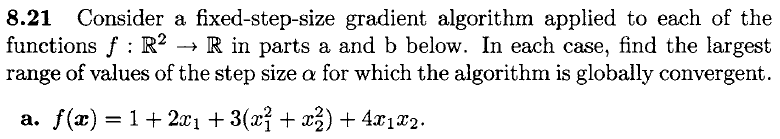

## a)

f = @(x1, x2) 1 + 2*x1 + 3*(x1^2+x2^2) + 4*x1*x2;

The quadratic form of the function *f* may be written as:


$$f\left(x\right)=\frac{1}{2}{\mathit{\mathbf{x}}}^T \mathbf{Qx}-{\mathit{\mathbf{b}}}^T \mathit{\mathbf{x}}+c$$


Where **Q** must be a symmetric matrix and is therefore given by:


$$Q=\left\lbrack \begin{array}{cc}
6 & 4\\
4 & 6
\end{array}\right\rbrack$$


Q = [6 4; 4 6]

Q =      6     4
     4     6


b = [-2; 0]

b =     -2
     0


c = 1

c = 1

f_quadratic = @(x1,x2) 0.5*[x1 x2]*Q*[x1; x2]-b'*[x1; x2]+c;

Then for a fixed-step-size gradient algorithm, the algorithm is globally convergent when $\alpha$is within the range:


$$0<\alpha<\frac{2}{\lambda_{max}(\mathbf{Q})}$$


The eigenvalues of $Q$ are given by:

eig_max = eigs(Q,1) % returns eigenvector with largest magnitude

eig_max = 10

The range of $\alpha$is then:

syms a
range = 0 < a < (2/eig_max)

$$range = \left(0<a\right)<\frac{1}{5}$$

## b)

A = [3 3; 1 3];
b = [16; 23];
c = pi^2;
f = @(x1, x2) [x1 x2]*A*[x1; x2] + b'*[x1; x2]+c;

The quadratic form of the function *f* may be written as:


$$f\left(x\right)=\frac{1}{2}{\mathit{\mathbf{x}}}^T \mathbf{Qx}-{\mathit{\mathbf{b}}}^T \mathit{\mathbf{x}}+c$$


Where $Q$ is a symmetric matrix, which is given by:


$$Q=A+A^T$$


Q = A+A'

Q =      6     4
     4     6


f_quadratic = @(x1,x2) 0.5*[x1 x2]*Q*[x1; x2]+b'*[x1; x2]+c;

Then for a fixed-step-size gradient algorithm, the algorithm is globally convergent when $\alpha$ is within the range:


$$0<\alpha<\frac{2}{\lambda_{max}(\mathbf{Q})}$$


The eigenvalues of $Q$ are given by:

eig_max = eigs(Q,1) % returns eigenvector with largest magnitude

eig_max = 10

The range of $\alpha$is then:

syms a
range = 0 < a < (2/eig_max)

$$range = \left(0<a\right)<\frac{1}{5}$$

## Exercise 8.25

clear;

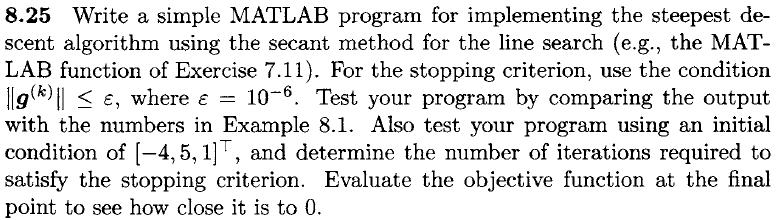

The following is given:

epsilon = 10e-6; % The search tolerance
x = [-4,5,1]'; % Initial point

The function from example 8.1 is:


$$f\left(x_1 ,x_2 ,x_3 \right)={\left(x_1 -4\right)}^4 +{\left(x_2 -3\right)}^2 +4{\left(x_3 +5\right)}^4$$


f = @(x1,x2,x3) (x1 - 4)^4 + (x2 - 3)^2 + 4*(x3 + 5)^4;

The derivative of the function is then:

syms x1 x2 x3
Df = [diff(f,x1), diff(f,x2), diff(f,x3)]
% Redefining Df as a function to simplify calculations
Df = @(x) [4*(x(1) - 4)^3, 2*(x(2) - 3), 16*(x(3) + 5)^4]';

A maximum number of iterations is chosen as arbitrarily high, to ensure the stopping criterion will be reached, as this exercise does not specify a maximum number of iterations.

max_N = 100; % Maximum number iterations to convergence
g = zeros(3,max_N); % Allocation of array

For each iteration, the step size $\alpha_k$ is chosen to achieve the maximum amount of decrease of the objective function. Specifically, this means $\alpha_k$ is chosen to minimize the function:


$$\alpha_k =\underset{\alpha \ge \text{ }0}{\mathrm{arg}\text{ }\mathrm{min}} f\left(x^{\left(k\right)} -\alpha \nabla f\left(x^{\left(k\right)} \right)\right)$$
 

This means that for each step, a line search is conducted in the direction $-\nabla f\left(x^{\left(k\right)} \right)$ until a minimizer $x^{\left(k+1\right)}$ is found.

for k = 1:max_N
    % Calculating the gradient from Df
    g(:,k) = Df(x(:,k));

    if( norm(g(:,k)) <= epsilon)
        disp('Steepest descent terminating with number of iterations:')
        disp(k)
        break; 
    end
    
    % Getting ready for secant line search of alpha (borrowed from http://www.engr.colostate.edu/~echong/ece520/matlab_demos/secant.m))
    epsilon_alpha =10e-5; % Line search tolerance (specified in exercise 7.10)
    max_alpha = 500; % Maximum number of line search iterations
    alpha      = epsilon_alpha;     
    d(:,k)     = -g(:,k);       % direction
    alpha_curr = 0;
    dphi_zero  = Df(x(:,k))'*d;
    dphi_curr  = dphi_zero;
    
    i=0;
    while abs(dphi_curr)>epsilon_alpha*abs(dphi_zero)
        
        alpha_old   = alpha_curr;      
        alpha_curr  = alpha;
        dphi_old    = dphi_curr;        
        dphi_curr   = Df(x(:,k) + alpha_curr*d(:,k))'*d(:,k); % Eq. p.119b
        alpha  = (dphi_curr*alpha_old-dphi_old*alpha_curr)/(dphi_curr-dphi_old); % Eq. p.118m
        
        i=i+1;
        
        if (i >= max_alpha)
            disp('Line search terminating with number of iterations:');
            disp(i);
            break;
        end
    end

    x(:,k+1) = x(:,k) - alpha * g(:,k);
    
    if( k == max_N )
        disp('Steepest descent terminating with maximum number of iterations')
    end
end
minimum = f(x(1,k),x(2,k),x(3,k));
disp('Minimum found:');
disp(minimum);

## Exercise 8.26

clear;

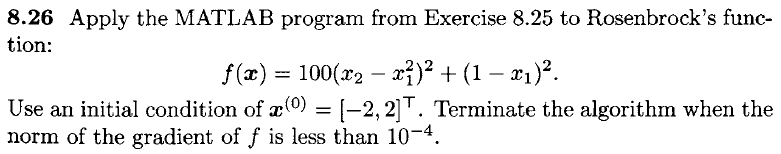

The following is given:

epsilon = 10e-4; % The search tolerance
x = [-2;2]; % Initial point

The function from example 8.1 is:


$$f\left(x_1 ,x_2 ,x_3 \right)={\left(x_1 -4\right)}^4 +{\left(x_2 -3\right)}^2 +4{\left(x_3 +5\right)}^4$$


f = @(x1,x2) 100*(x2-x1^2)^2+(1-x1)^2;

The derivative of the function is then:

syms x1 x2
Df = [diff(f,x1), diff(f,x2)]
% Redefining Df as a function to simplify calculations
Df = @(x) [2*x(1)-400*x(1)*(x(2)-x(1)^2)-2 200*x(2)-200*x(1)^2]

A maximum number of iterations is chosen as arbitrarily high, to ensure the stopping criterion will be reached, as this exercise does not specify a maximum number of iterations.

max_N = 100000; % Maximum number iterations to convergence
g = zeros(2,max_N); % Allocation of array

For each iteration, the step size $\alpha_k$ is chosen to achieve the maximum amount of decrease of the objective function. Specifically, this means $\alpha_k$ is chosen to minimize the function:


$$\alpha_k =\underset{\alpha \ge \text{ }0}{\mathrm{arg}\text{ }\mathrm{min}} f\left(x^{\left(k\right)} -\alpha \nabla f\left(x^{\left(k\right)} \right)\right)$$
 

This means that for each step, a line search is conducted in the direction $-\nabla f\left(x^{\left(k\right)} \right)$ until a minimizer $x^{\left(k+1\right)}$ is found.

for k = 1:max_N
    % Calculating the gradient from Df
    g(:,k) = Df(x(:,k));
   
    if( norm(g(:,k)) <= epsilon)
        disp('Steepest descent terminating with number of iterations:')
        disp(k)
        break;
    end
    
    % Getting ready for secant line search of alpha (borrowed from http://www.engr.colostate.edu/~echong/ece520/matlab_demos/secant.m))
    epsilon_alpha =10e-5; % Line search tolerance (specified in exercise 7.10)
    max_alpha = 500; % Maximum number of line search iterations
    alpha      = epsilon_alpha;     
    d(:,k)     = -g(:,k);       % direction
    alpha_curr = 0;
    dphi_zero  = Df(x(:,k))*d;
    dphi_curr  = dphi_zero;
    
    i=0;
    while abs(dphi_curr)>epsilon_alpha*abs(dphi_zero)
        
        alpha_old   = alpha_curr;      
        alpha_curr  = alpha;
        dphi_old    = dphi_curr;        
        dphi_curr   = Df(x(:,k) + alpha_curr*d(:,k))*d(:,k); % Eq. p.119b
        alpha  = (dphi_curr*alpha_old-dphi_old*alpha_curr)/(dphi_curr-dphi_old); % Eq. p.118m
        
        i=i+1;
        
        if (i >= max_alpha)
            break;
        end
    end

    x(:,k+1) = x(:,k) - alpha * g(:,k);
    
    if( k == max_N )
        disp('Steepest descent terminating with maximum number of iterations')
    end
end
minimum = f(x(1,k),x(2,k));
disp('Minimum found:');
disp(minimum);